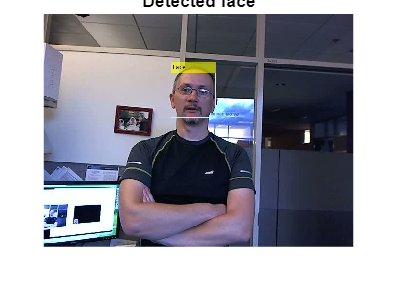

% Create a cascade detector object.
faceDetector = vision.CascadeObjectDetector();

% Read a video frame and run the detector.
videoFileReader = VideoReader('visionface.avi');
videoFrame      = readFrame(videoFileReader);
bbox            = step(faceDetector, videoFrame);

% Draw the returned bounding box around the detected face.
videoOut = insertObjectAnnotation(videoFrame,'rectangle',bbox,'Face');
figure, imshow(videoOut), title('Detected face');

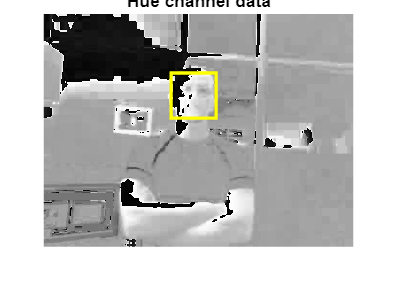

[hueChannel,~,~] = rgb2hsv(videoFrame);

% Display the Hue Channel data and draw the bounding box around the face.
figure, imshow(hueChannel), title('Hue channel data');
rectangle('Position',bbox(1,:),'LineWidth',2,'EdgeColor',[1 1 0])

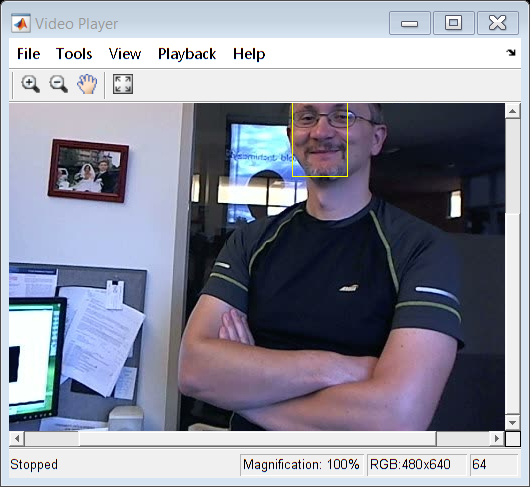

noseDetector = vision.CascadeObjectDetector('Nose', 'UseROI', true);
noseBBox     = step(noseDetector, videoFrame, bbox(1,:));

% Create a tracker object.
tracker = vision.HistogramBasedTracker;

% Initialize the tracker histogram using the Hue channel pixels from the
% nose.
initializeObject(tracker, hueChannel, noseBBox(1,:));

% Create a video player object for displaying video frames.
videoPlayer  = vision.VideoPlayer;

% Track the face over successive video frames until the video is finished.
while hasFrame(videoFileReader)

    % Extract the next video frame
    videoFrame = readFrame(videoFileReader);

    % RGB -> HSV
    [hueChannel,~,~] = rgb2hsv(videoFrame);

    % Track using the Hue channel data
    bbox = step(tracker, hueChannel);

    % Insert a bounding box around the object being tracked
    videoOut = insertObjectAnnotation(videoFrame,'rectangle',bbox,'Face');

    % Display the annotated video frame using the video player object
    step(videoPlayer, videoOut);

end

% Release resources
release(videoPlayer);